# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


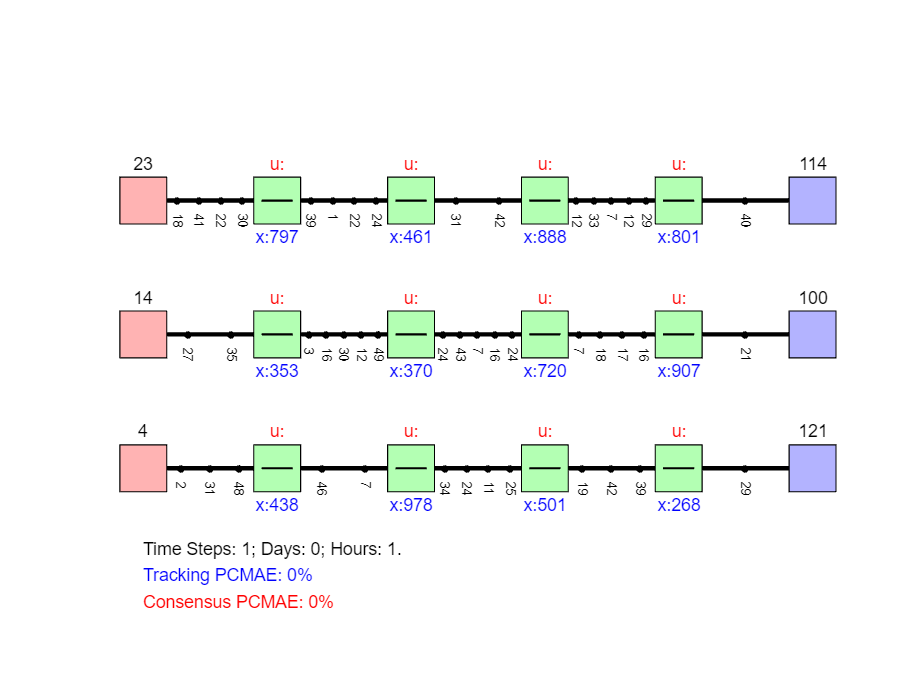


% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal; axis off;
net.draw(1);


tMax = 24*30 + 1 % 4 weeks

tMax = 721

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display

save(['tempNet',num2str(caseNum)])
perfData.cumVals = [];
perfData.conHist = [];
perfData.traHist = [];
perfData.caseName{1} = 'CaseNames';
save('caseNum.mat','caseNum','perfData')

Steady state control: K = 0, L = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


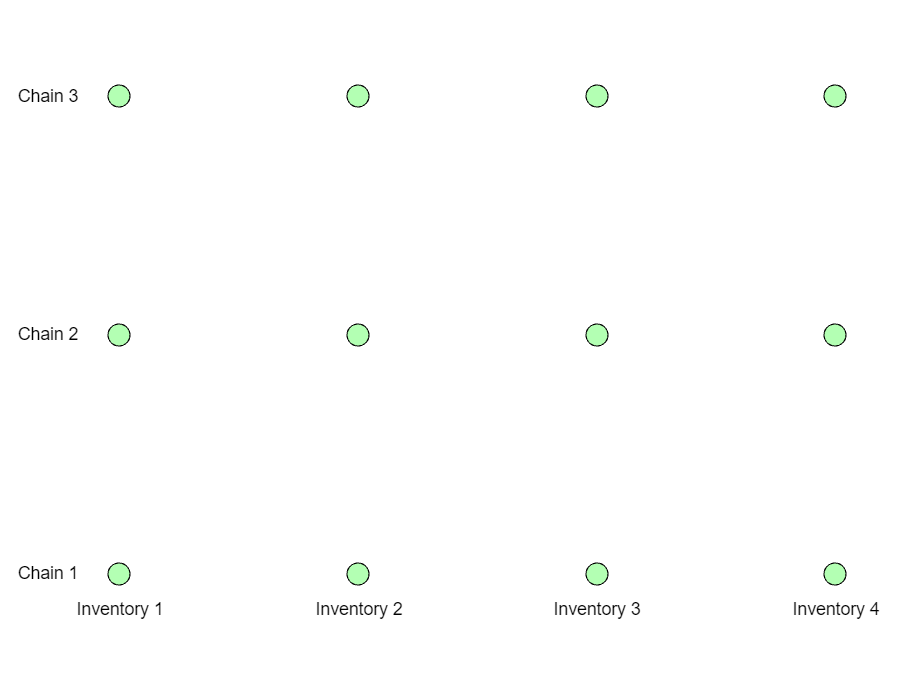

net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
figNum = figNum + 1;
figure(figNum); 
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

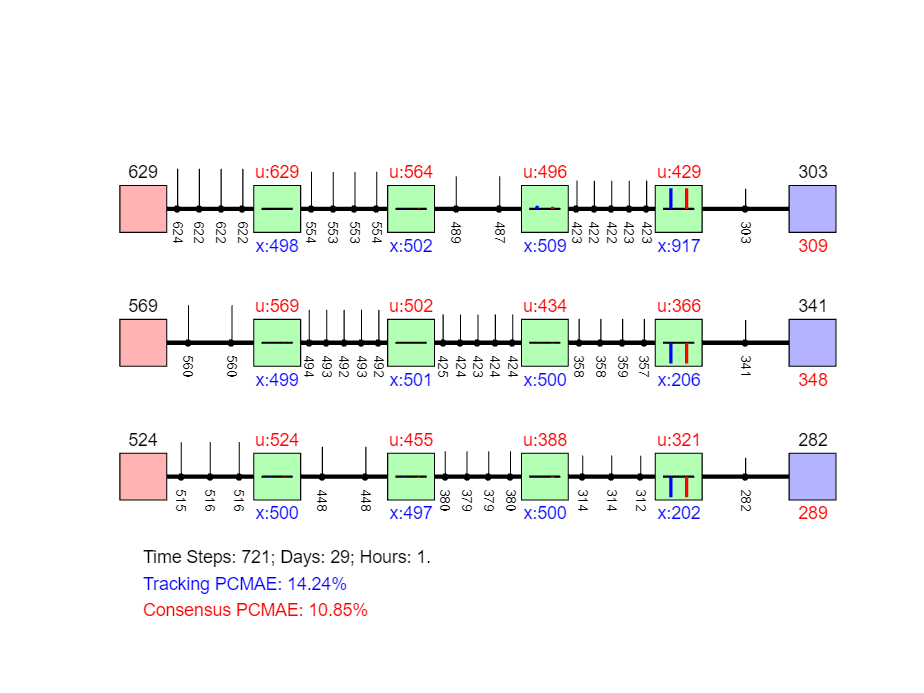

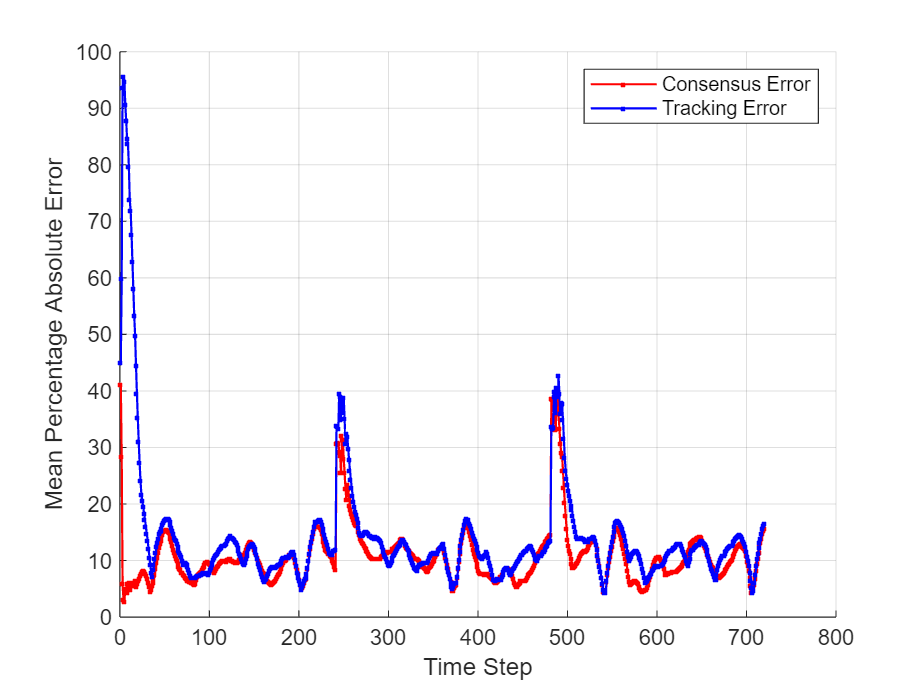

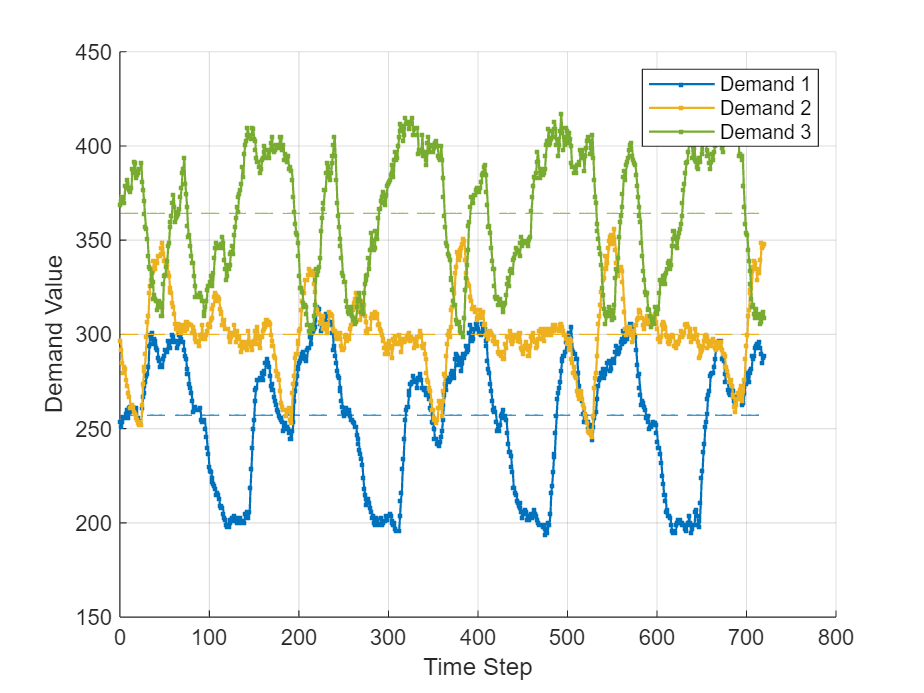


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();

    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotDemandProfiles();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError]

perfData = struct with fields:
     cumVals: [71.2230 54.2503]
     conHist: []
     traHist: []
    caseName: {'CaseNames'}


perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SSC';
save('caseNum.mat','caseNum','perfData')

Strict local control: K = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    deltaCostCoef = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.0549   -0.0350   -0.0208   -0.0166   -0.0599   -0.0720   -0.0837   -0.0372   -0.0422   -0.0229   -0.0249   -0.0268   -0.0288   -0.0180   -0.0194   -0.0212
    0.3612   -0.0532   -0.0238   -0.0199    0.4087    0.1051    0.0248   -0.0590   -0.0692   -0.0260   -0.0283   -0.0309   -0.0368   -0.0211   -0.0224   -0.0241
    0.0157    0.3208   -0.0464   -0.0381    0.0189    0.0140    0.0091    0.3584    0.1017   -0.0505   -0.0551   -0.0612   -0.0732   -0.0402   -0.0426   -0.0459
   -0.0001    0.0007    0.2913   -0.1274    0.0008    0.0009    0.0010    0.0025    0.0021    0.3330    0.0752    0.0152    0.0076   -0.1331   -0.1426   -0.1528


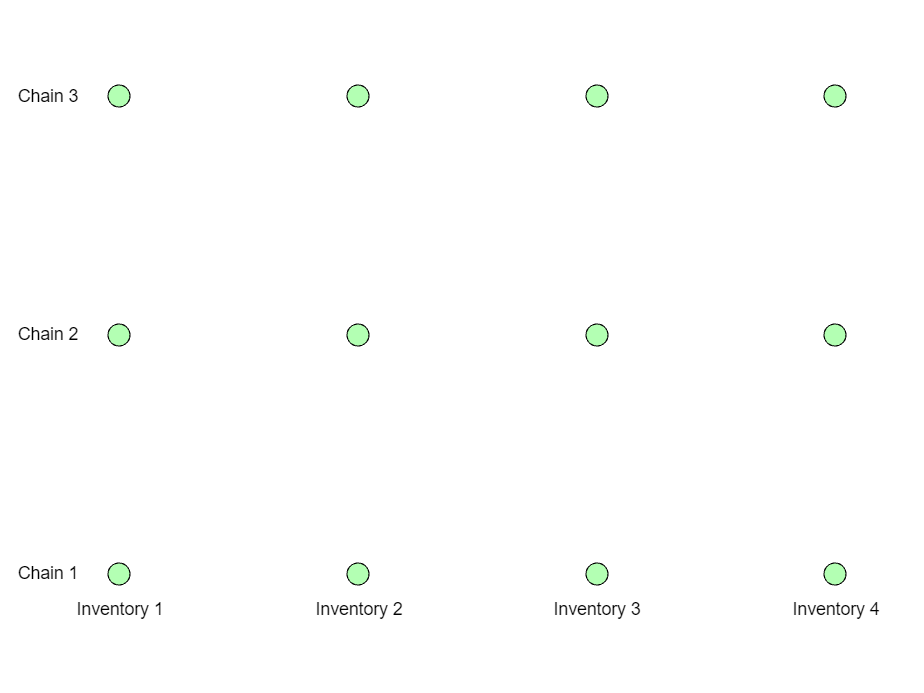

net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

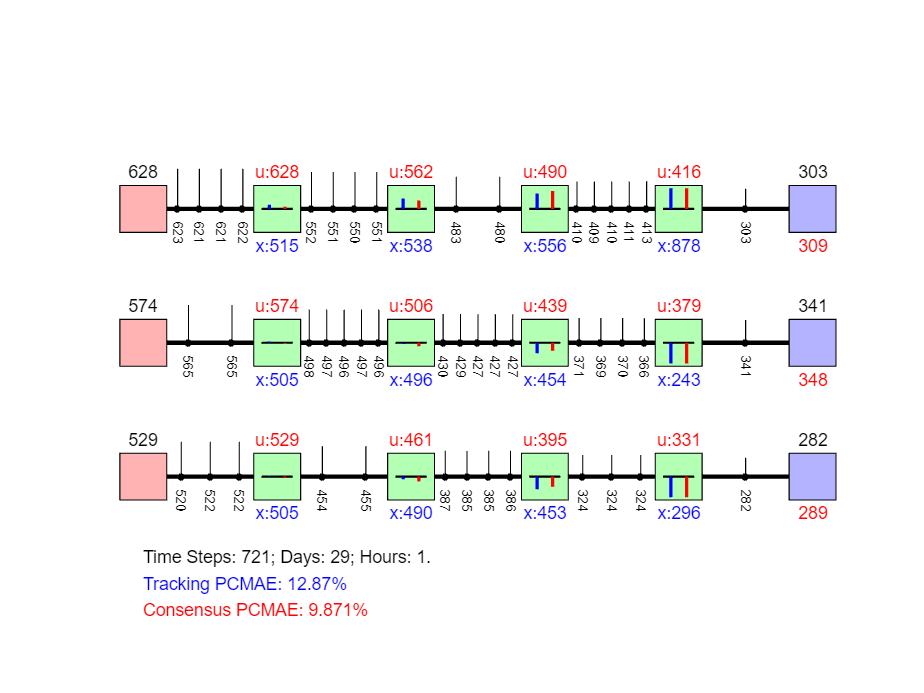

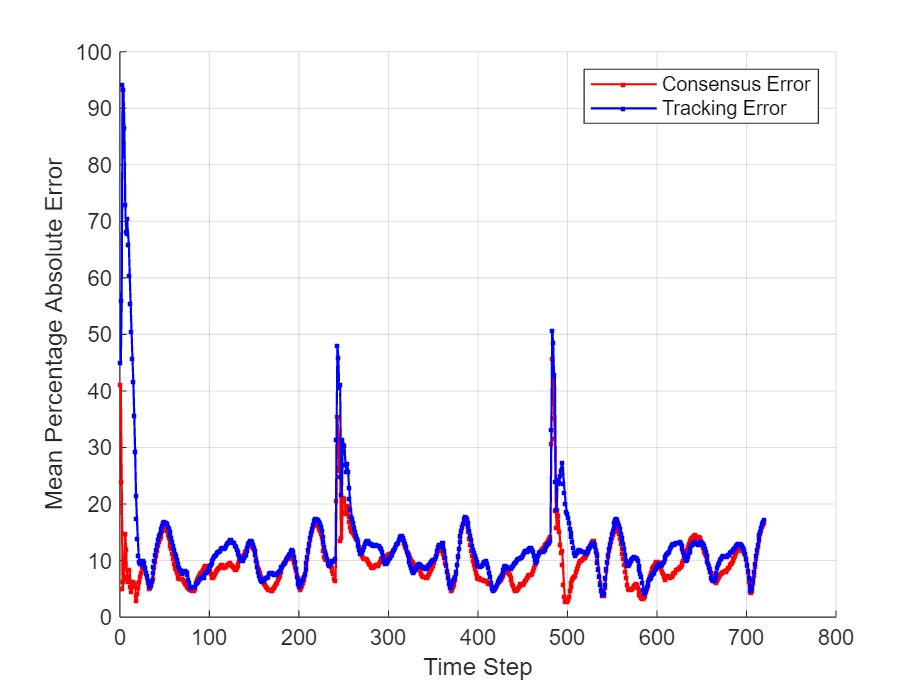


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError]

perfData = struct with fields:
     cumVals: [2×2 double]
     conHist: [41.1778 28.3778 5.8667 3.0667 2.7000 4.9556 5.1333 5.9111 4.2889 5 6.2000 4.8111 5.7778 5.5889 6.1556 6.0778 6.4444 5.5000 5.3667 5.9222 6.4667 6.8667 7.3333 7.7111 8.0889 8.1556 8.1222 7.9778 7.7444 7.3444 6.7778 6.0667 … ] (1×720 double)
     traHist: [45.0333 59.8167 93.6000 95.7000 94.8000 90.7167 87.9000 84.5833 83.8000 79.7667 73.8667 71.9000 67.7167 62.8500 58.1333 53.3167 49.7500 44.4500 39.6167 35.2167 31.1000 27.4000 24.1000 21.7000 20.5667 19.5000 18.4000 … ] (1×720 double)
    caseName: {'CaseNames'  'SSC'}


perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SLC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Hard Graph - 2

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
d1 = 1;
d2 = -1; %-10
d3 = 1;
d4 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

Best parameter combination found:
Minimum objective value: 0.092853
pVal: 0.01
deltaCostCoef: 1
gammaCostCoef: 0.01
comCostLimit: 0.01
LNorm: 4.745
KNorm: 0.097347
gammaTilde: 116.8652
KLinks: 75


pVal = 0.0100

deltaCostCoef = 1

gammaCostCoef = 0.0100

comCostLimit = 0.0100

KLinks = 75


%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 4.9467

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   0


gammaTildeVal = 1.5507e-11

KNormVal = 0.0643

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6976   -0.7967   -0.8561   -0.6941   -0.7751   -0.8006   -0.7673   -0.8852   -0.9279   -0.9513   -1.0356   -1.0961   -1.1501   -0.7712   -0.8568   -0.9465
    0.0093   -0.5250   -0.5167   -0.4211    0.0100   -0.1682   -0.2216   -0.5838   -0.6181   -0.5743   -0.6224   -0.6764   -0.6868   -0.4679   -0.5199   -0.5786
   -0.2501   -0.1626   -0.5628   -0.4480   -0.2777   -0.2785   -0.2624   -0.1802   -0.2913   -0.6249   -0.6762   -0.7187   -0.7494   -0.4977   -0.5530   -0.6041
   -0.1032   -0.1324    0.0295   -0.3587   -0.1145   -0.1099   -0.0973   -0.1479   -0.1437    0.0323   -0.1157   -0.1830   -0.2131   -0.3987   -0.4434   -0.4878


net.KGlobal

ans =    -0.0047    0.0555    0.0040    0.0068    0.0118    0.0036    0.0050    0.0067    0.0036    0.0044    0.0060    0.0082
   -0.0014   -0.0021    0.0120    0.0032    0.0013    0.0027    0.0020    0.0020    0.0019    0.0015    0.0029    0.0037
    0.0027   -0.0006   -0.0042    0.0107    0.0028    0.0021    0.0043    0.0020    0.0041    0.0026    0.0020    0.0027
    0.0045    0.0025    0.0042   -0.0071    0.0039    0.0031    0.0019    0.0041    0.0054    0.0033    0.0026    0.0015
    0.0373    0.0029    0.0058    0.0094   -0.0011    0.0090    0.0057    0.0074    0.0173    0.0025    0.0051    0.0083
    0.0009   -0.0016    0.0015    0.0026   -0.0011   -0.0050    0.0022    0.0029    0.0014   -0.0013    0.0020    0.0032
    0.0012    0.0004   -0.0011    0.0028    0.0011   -0.0004   -0.0047    0.0018    0.0021    0.0005    0.0003    0.0022
    0.0022    0.0016    0.0013   -0.0010    0.0026    0.0019    0.0006   -0.0054    0.0033    0.0017    0.0012    0.0002
    0.0037    0.0049    0.

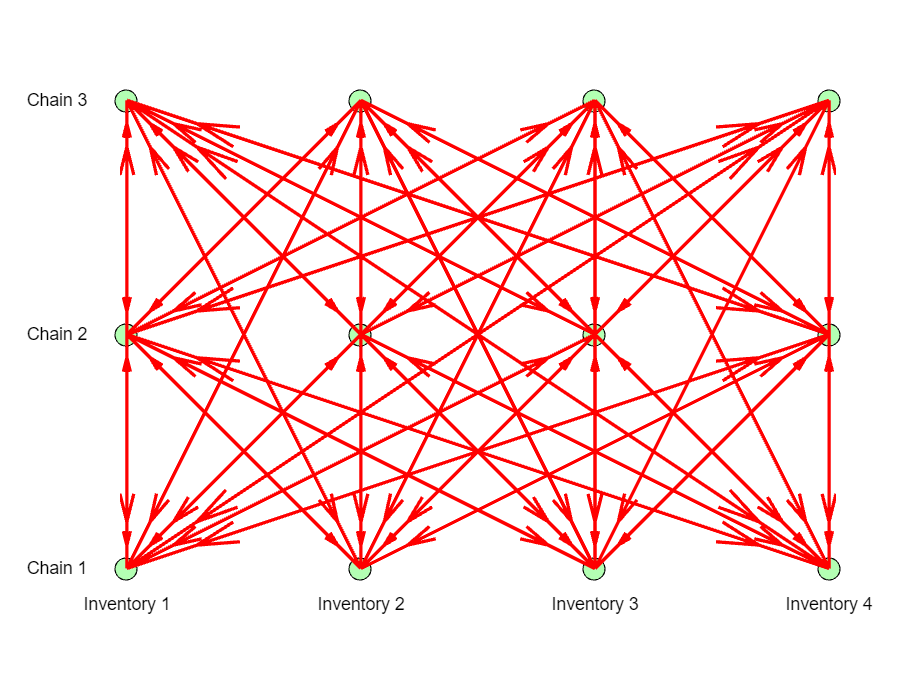


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

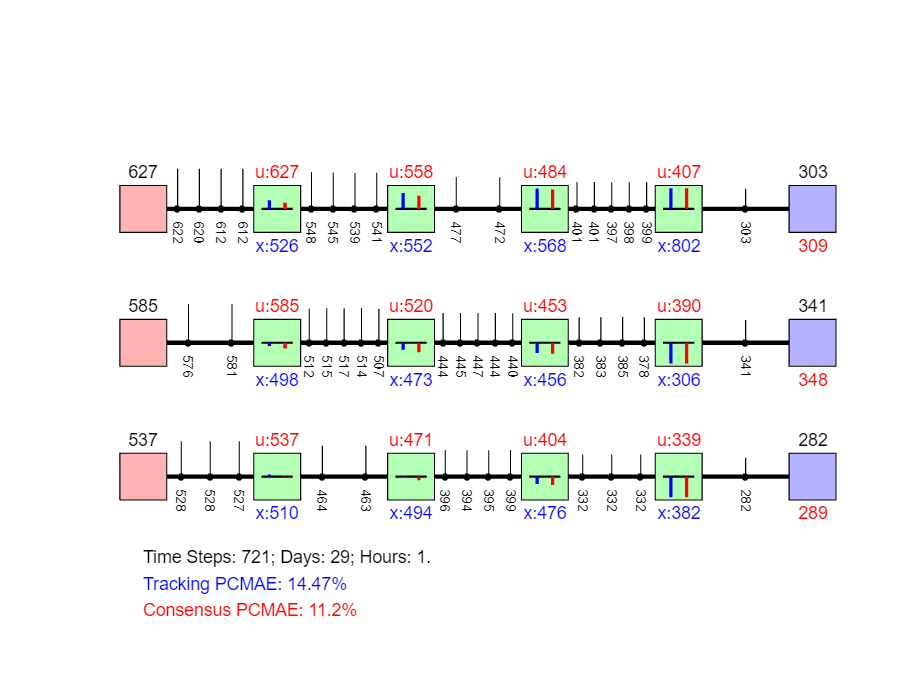

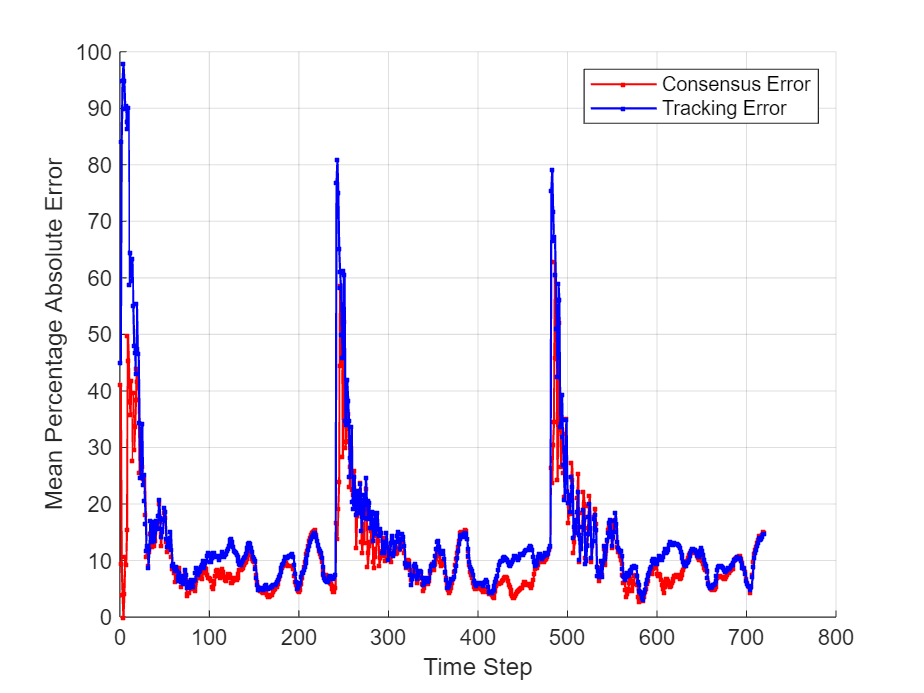


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError]

perfData = struct with fields:
     cumVals: [3×2 double]
     conHist: [2×720 double]
     traHist: [2×720 double]
    caseName: {'CaseNames'  'SSC'  'SLC'}


perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DHC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Soft Graph

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
d1 = 1;
d2 = -1; %-10
d3 = 1;
d4 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

Best parameter combination found:
Minimum objective value: 0.092853
pVal: 0.01
deltaCostCoef: 1
gammaCostCoef: 0.01
comCostLimit: 0.01
LNorm: 4.745
KNorm: 0.097347
gammaTilde: 116.8652
KLinks: 75


pVal = 0.0100

deltaCostCoef = 1

gammaCostCoef = 0.0100

comCostLimit = 0.0100

KLinks = 75


%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 4.9467

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 162.0769

KNormVal = 0.0874

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6976   -0.7967   -0.8561   -0.6941   -0.7751   -0.8006   -0.7673   -0.8852   -0.9279   -0.9513   -1.0356   -1.0961   -1.1501   -0.7712   -0.8568   -0.9465
    0.0093   -0.5250   -0.5167   -0.4211    0.0100   -0.1682   -0.2216   -0.5838   -0.6181   -0.5743   -0.6224   -0.6764   -0.6868   -0.4679   -0.5199   -0.5786
   -0.2501   -0.1626   -0.5628   -0.4480   -0.2777   -0.2785   -0.2624   -0.1802   -0.2913   -0.6249   -0.6762   -0.7187   -0.7494   -0.4977   -0.5530   -0.6041
   -0.1032   -0.1324    0.0295   -0.3587   -0.1145   -0.1099   -0.0973   -0.1479   -0.1437    0.0323   -0.1157   -0.1830   -0.2131   -0.3987   -0.4434   -0.4878


net.KGlobal

ans =    -0.0252    0.0074    0.0228    0.0295    0.0034    0.0119    0.0195    0.0219    0.0089    0.0163    0.0246    0.0268
    0.0041   -0.0053    0.0008    0.0009    0.0014    0.0001    0.0002    0.0002    0.0013    0.0011    0.0001    0.0001
    0.0037    0.0014   -0.0051    0.0012    0.0021    0.0004         0    0.0002    0.0024    0.0004    0.0010    0.0000
    0.0042    0.0022    0.0012   -0.0044    0.0030    0.0010    0.0001         0    0.0036    0.0010    0.0000    0.0009
    0.0082    0.0026    0.0051    0.0323   -0.0008    0.0008    0.0021    0.0194    0.0003    0.0009    0.0023    0.0225
    0.0001    0.0000    0.0000         0    0.0001         0         0         0    0.0001         0    0.0000         0
    0.0001    0.0001         0         0    0.0001    0.0001         0         0    0.0001    0.0000         0         0
    0.0001    0.0001    0.0000         0    0.0001    0.0001    0.0001         0    0.0001    0.0001         0         0
    0.0334    0.0292    0.

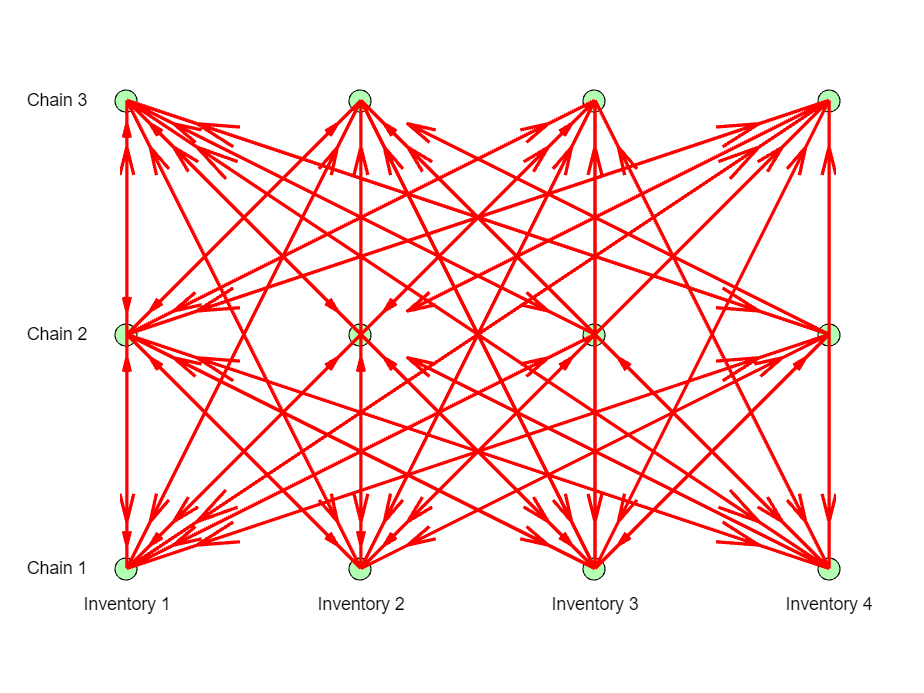


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

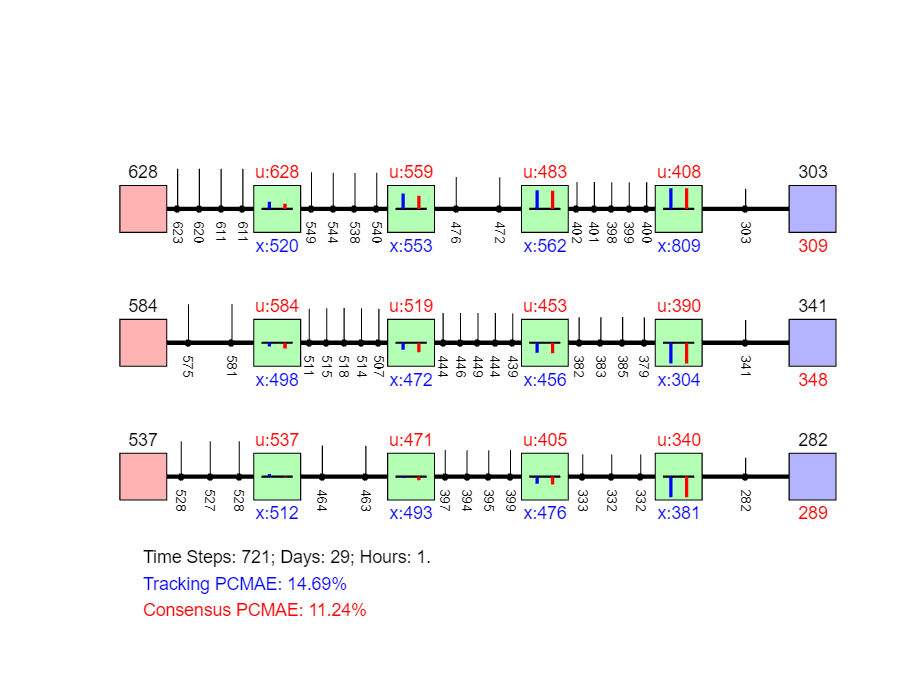

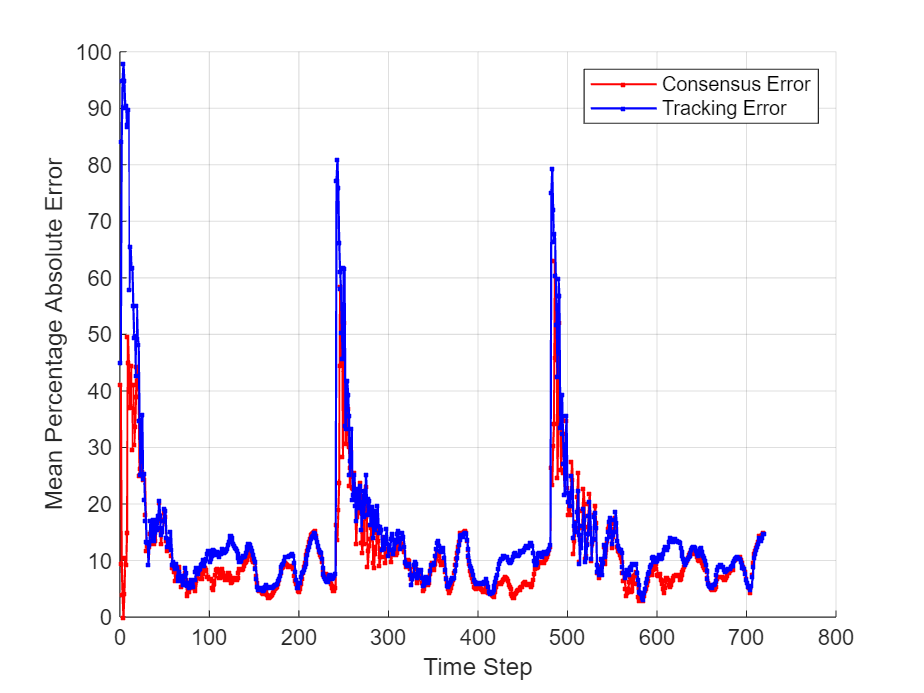


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:(tMax-1)
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError]

perfData = struct with fields:
     cumVals: [4×2 double]
     conHist: [3×720 double]
     traHist: [3×720 double]
    caseName: {'CaseNames'  'SSC'  'SLC'  'DHC'}


perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DSC';
save('caseNum.mat','caseNum','perfData')

perfData.cumVals

ans =    71.2230   54.2503
   64.3583   49.3556
   72.3275   56.0180
   73.4259   56.2200


% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)

Summary Plots (for the paper)

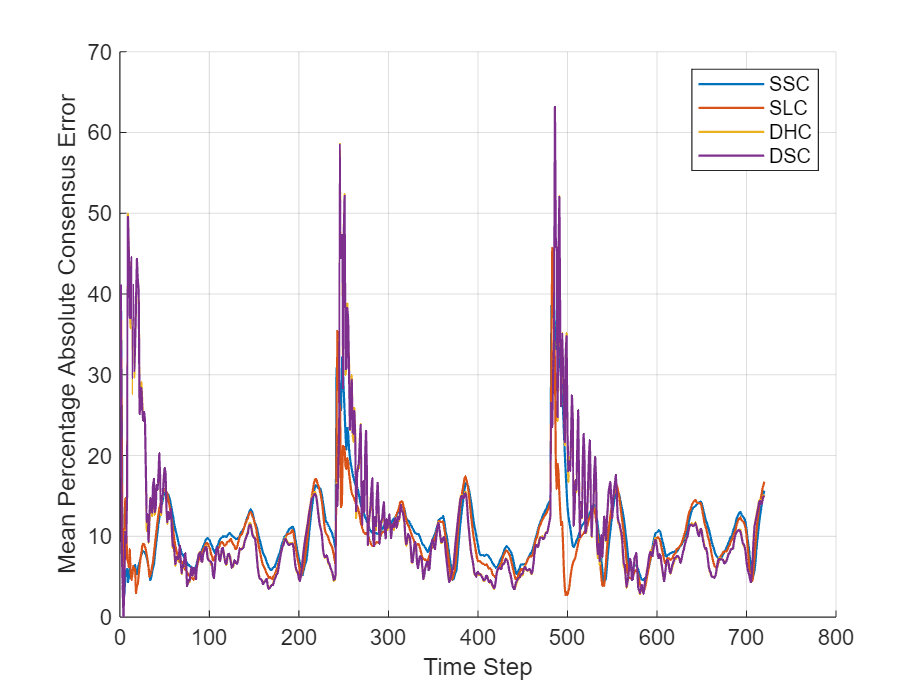

close all
clc

conHist = perfData.conHist;
traHist = perfData.traHist;
caseNames = perfData.caseName;
numCases = size(conHist,1);

L = size(conHist,2);

figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, conHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Consensus Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(conHist(3,:)>=conHist(4,:))*100/L

percentageImprovement = 49.7222

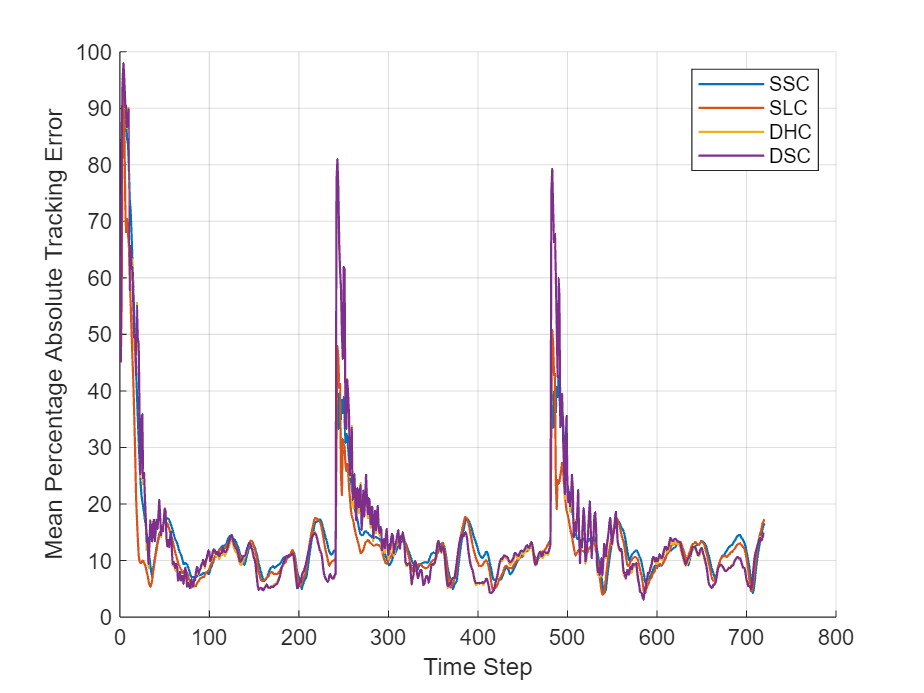


figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, traHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Tracking Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(traHist(3,:)>=traHist(4,:))*100/L

percentageImprovement = 27.9167



net.printDefaultProperties()

Supply Chain Network Default Parameters:

--- Supply Class ---
supRateMax: 100000.000000

--- Demand Class ---
dailyMeans Obtained using: 100 + 20*randi([1,numOfChains],7,1) + 20*demId;
Chain 1.000000
dailyMeans:    250
   300
   300
   250
   200
   200
   300

demRateMean (mean): 257.142857
demRateStd (0.1x): 25.714286
Chain 2.000000
dailyMeans:    250
   350
   300
   300
   300
   300
   300

demRateMean (mean): 300.000000
demRateStd (0.1x): 30.000000
Chain 3.000000
dailyMeans:    400
   300
   400
   300
   350
   400
   400

demRateMean (mean): 364.285714
demRateStd (0.1x): 36.428571

--- Inventory Class ---
refLevel: 500.000000
maxLevel: 1000.000000
minLevel: 10.000000
perishRate: 0.100000
wasteRateMean Obtained using: 5 + randi([1,5])
wasteRateStd Obtained using: 0.2*mean
Chain 1.000000, Inventory 1.000000
wasteRateMean: 9.000000
wasteRateStd (0.2x): 1.800000
Chain 1.000000, Inventory 2.000000
wasteRateMean: 9.000000
wasteRateStd (0.2x): 1.800000
Chain 1.000000, Inventory 3.000